% Clear workspace
clear; close all; clc;
 
% Images Datapath – Please modify your path accordingly 
datapath='CTDataset';
 
% Image Datastore
imds=imageDatastore(datapath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
% Determine the split up
total_split=countEachLabel(imds)

total_split = 2×2 table
       Label        Count
    ____________    _____

    COVID-19        7495 
    Non-COVID-19     944 


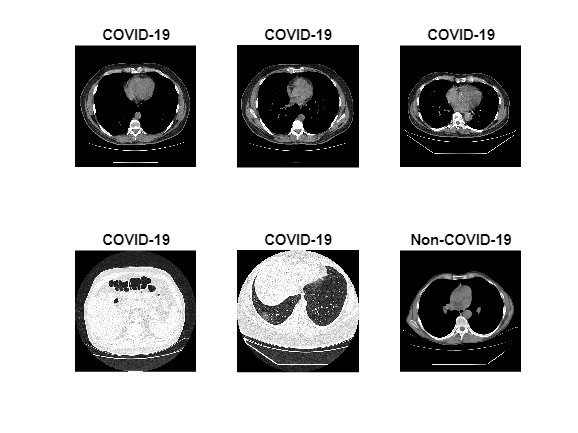



% Number of Images
num_images=length(imds.Labels);

% Visualize random images
perm=randperm(num_images,6);
figure;
for idx=1:length(perm)
    
    subplot(2,3,idx);
    imshow(imread(imds.Files{perm(idx)}));
    title(sprintf('%s',imds.Labels(perm(idx))))
    
end



% Number of folds
num_folds=2;

% Loop for each fold
for fold_idx=1:num_folds
    
    fprintf('Processing %d among %d folds \n',fold_idx,num_folds);
    
   % Test Indices for current fold
    test_idx=fold_idx:num_folds:num_images;

    % Test cases for current fold
    imdsTest = subset(imds,test_idx);
    
    % Train indices for current fold
    train_idx=setdiff(1:length(imds.Files),test_idx);
    
    % Train cases for current fold
    imdsTrain = subset(imds,train_idx);
 
    % ResNet Architecture 
    net=resnet50;
    lgraph = layerGraph(net);
    clear net;
    
    % Number of categories
    numClasses = numel(categories(imdsTrain.Labels));
    
    % New Learnable Layer
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
    % Replacing the last layers with new layers
    lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
    newsoftmaxLayer = softmaxLayer('Name','new_softmax');
    lgraph = replaceLayer(lgraph,'fc1000_softmax',newsoftmaxLayer);
    newClassLayer = classificationLayer('Name','new_classoutput');
    lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);
    
    
    % Preprocessing Technique
    imdsTrain.ReadFcn = @(filename)preprocess_Xray(filename);
    imdsTest.ReadFcn = @(filename)preprocess_Xray(filename);
    
    % Training Options, we choose a small mini-batch size due to limited images 
    options = trainingOptions('adam',...
        'MaxEpochs',30,'MiniBatchSize',8,...
        'Shuffle','every-epoch', ...
        'InitialLearnRate',1e-4, ...
        'Verbose',false, ...
        'Plots','training-progress');
    
    % Data Augumentation
    augmenter = imageDataAugmenter( ...
        'RandRotation',[-5 5],'RandXReflection',1,...
        'RandYReflection',1,'RandXShear',[-0.05 0.05],'RandYShear',[-0.05 0.05]);
    
    % Resizing all training images to [224 224] for ResNet architecture
    auimds = augmentedImageDatastore([224 224],imdsTrain,'DataAugmentation',augmenter);
    
    % Training
    netTransfer = trainNetwork(auimds,lgraph,options);
    
    % Resizing all testing images to [224 224] for ResNet architecture   
    augtestimds = augmentedImageDatastore([224 224],imdsTest);
   
    % Testing and their corresponding Labels and Posterior for each Case
    [predicted_labels(test_idx),posterior(test_idx,:)] = classify(netTransfer,augtestimds);
    
    % Save the Independent ResNet Architectures obtained for each Fold
    save(sprintf('ResNet50_%d_among_%d_folds',fold_idx,num_folds),'netTransfer','test_idx','train_idx');
    
    % Clearing unnecessary variables 
    clearvars -except fold_idx num_folds num_images predicted_labels posterior imds netTransfer;
    
end

Processing 1 among 2 folds 
Processing 2 among 2 folds 


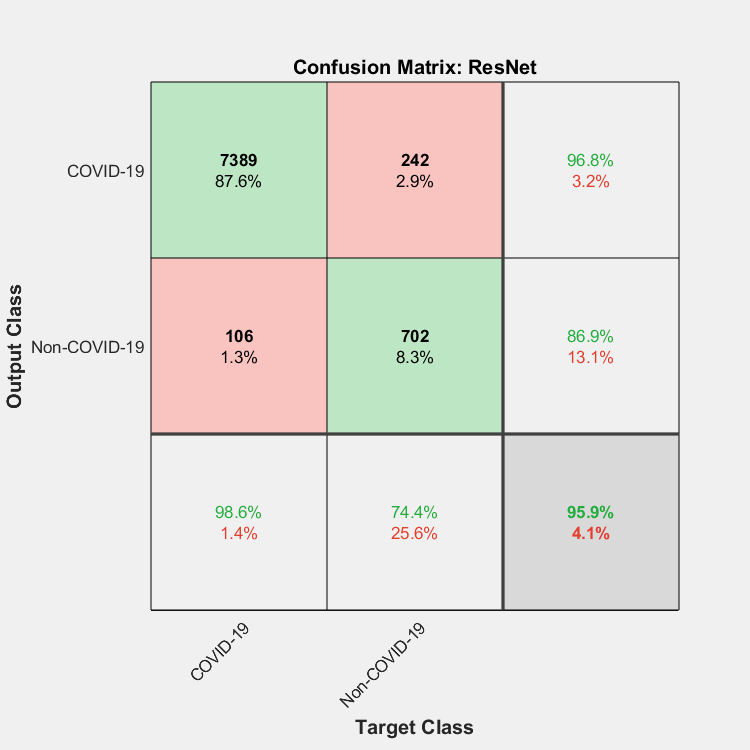



% Actual Labels
actual_labels=imds.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels,predicted_labels')
title('Confusion Matrix: ResNet');

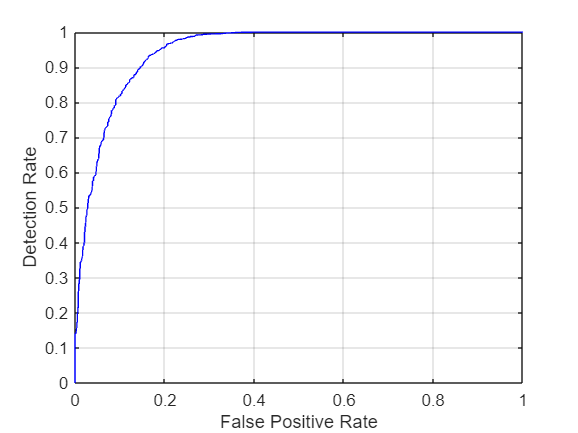



test_labels=double(nominal(imds.Labels));

% ROC Curve - Our target class is the first class in this scenario 
[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');


% Area under the ROC curve value
AUC

AUC = single
0.9467


cm = confusionmat(actual_labels, predicted_labels);
cmt = cm'

cmt =         7389         242
         106         702



diagonal = diag(cmt)

diagonal =         7389
         702


sum_of_rows = sum(cmt, 2)

sum_of_rows =         7631
         808



precision = diagonal ./ sum_of_rows

precision =     0.9683
    0.8688


overall_precision = mean(precision)

overall_precision = 0.9185


sum_of_columns = sum(cmt, 1)

sum_of_columns =         7495         944



recall = diagonal ./ sum_of_columns'

recall =     0.9859
    0.7436


overall_recall = mean(recall)

overall_recall = 0.8648


f1_score = 2*((overall_precision*overall_recall)/(overall_precision+overall_recall))

f1_score = 0.8908

function Iout = preprocess_Xray(filename)
% This function preprocesses the given X-ray image by converting it into
% grayscale if required and later converting to 3-channel image to adapt to
% existing deep learning architectures 


% Read the Filename
I = imread(filename);

% Some images might be RGB, convert them to Grayscale
if ~ismatrix(I)
    I=rgb2gray(I); 
end

% Replicate the image 3 times to create an RGB image
Iout = cat(3,I,I,I);

end